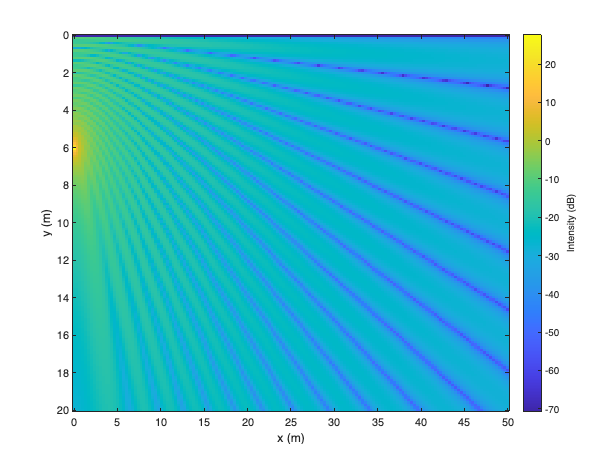

f = 2240; % frequency in Hz
d = 6; % Source Depth
c = 1500 ; % Speed of sound (m/s)


dmax = 10;
Lx = 5*dmax;
Ly = 2*dmax;
Nx = 150;
Ny = Nx;
x = linspace(0,Lx,Nx);
y = linspace(0,Ly,Ny);

[X,Y] = meshgrid(x,y);

r1 = sqrt(X.^2 + (Y-d).^2);
r2 = sqrt(X.^2 + (Y+d).^2);

p1 = exp(1i*2*pi*f*r1/c)./r1;
p2 = exp(1i*2*pi*f*r2/c)./r2;
p = p1 - p2;

plotType = 1;

if plotType == 0
    imagesc(x,y,real(p))
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Pressure (Pa)';

else
    imagesc(x,y,10*log10(abs(p).^2))
    a = gca;
    a.XLabel.String = 'x (m)';
    a.YLabel.String = 'y (m)';
    c1 = colorbar;
    c1.Label.String = 'Intensity (dB)';
end